### Init and load torque from excel:

clear
% Increase default font sizes for axes, legend, and text
set(groot, 'DefaultAxesFontSize',   14);
set(groot, 'DefaultLegendFontSize', 14);
set(groot, 'DefaultTextFontSize',   14);
load("airfoil.mat")
load("wing_opt.mat")
load("scr_s0.mat")
load("Farror.mat")
data = load("Wing_Load_Positive.mat")

data = struct with fields:
    data: [60×4 table]


y0 = [-flip(data.data.Var1); data.data.Var1(2:end)];
S0 = [flip(data.data.Var2); data.data.Var2(2:end)];
M0 = [flip(data.data.Var3); data.data.Var3(2:end)];
tau0 = [flip(data.data.Var4); data.data.Var4(2:end)];

M = interp1(y0, M0, wing_opt.stripy,'spline');
tau = interp1(y0, tau0, wing_opt.stripy,'spline');
S = interp1(y0, S0, wing_opt.stripy,'spline');

data = load("Wing_Load_Negative.mat")

data = struct with fields:
    data: [60×4 table]


y0 = [-flip(data.data.Var1); data.data.Var1(2:end)];
S0 = [flip(data.data.Var2); data.data.Var2(2:end)];
M0 = [flip(data.data.Var3); data.data.Var3(2:end)];
tau0 = [flip(data.data.Var4); data.data.Var4(2:end)];

Mneg = interp1(y0, M0, wing_opt.stripy,'spline'); 
tauneg = interp1(y0, tau0, wing_opt.stripy,'spline');
Sneg = interp1(y0, S0, wing_opt.stripy,'spline');

pltidx=1

pltidx = 1

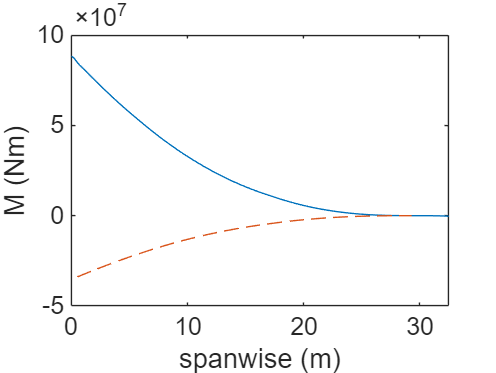

figure(pltidx)
clf;
plot(wing_opt.stripy, M)
hold on
plot(y0, M0,'--')
xlabel("spanwise (m)")
ylabel("M (Nm)")
xlim([0 wing_opt.b/2])

pltidx = pltidx + 1;

Material:

Al7068 =material(); %Aluminum 2024 T861
Al7068.E = 71.2e9; %E - 72-75.7 GPa (@23degC is 73)
Al7068.sigma_y = 648e6; %sigma_y - 400-462 MPa (@23degC is 441)
Al7068.G = 28.5e9; %G - 28-29.4 GPa
Al7068.sigma_y_tensile = 683e6;
Al7068.rho = 2850;
Al7068.price = 3.61;

Al2024 = material();
Al2024.E = 72e9; %E - 72-75.7 GPa (@23degC is 73)
Al2024.sigma_y = 400e6; %sigma_y - 400-462 MPa (@23degC is 441)
Al2024.G = 28e9; %G - 28-29.4 GPa
Al2024.sigma_y_tensile = 441e6;
Al2024.rho = 2780;
Al2024.price = 1.88;

sigma_max = 296e6; %maximum allowable stress

## **WingBox geometry (unchanged throughout)**

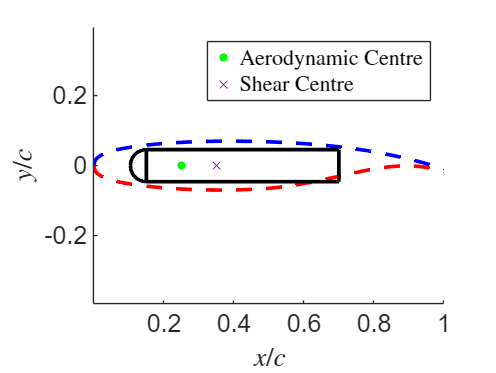

D = 6.38;
wb = wingbox();
%define geometry
wb.b2_c = mean(airfoil.uppershape(:,2) - airfoil.lowershape(:,2));
wb.b_c = 0.15;
wb.c_c = 0.7 - wb.b_c;
%wb = wb.calcR();
wb.R_c = wb.b2_c/2;
%define stringers
wb.L = 1;
%show wingbox:
figure(1)
clf;
wb.drawwithAirfoil(airfoil)
hold on
scatter((wb.b_c + wb.c_c)/2,0,'x')
legend("","","Aerodynamic Centre","","","","","","","","Shear Centre","Interpreter","latex")
xlabel("$x/c$","Interpreter","latex")
ylabel("$y/c$","Interpreter","latex")
print(gcf, fullfile('images', 'wingbox.png'), '-dpng', '-r300');

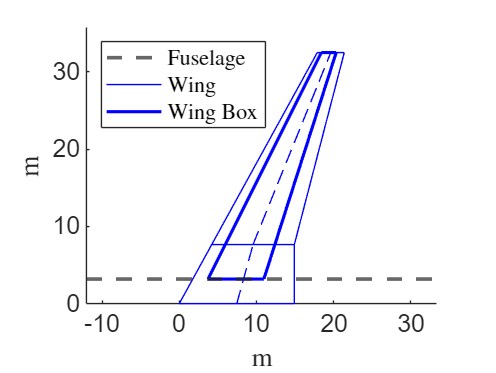


figure(2)
clf;
yline(D/2,'--','LineWidth',2)
hold on
wing_opt.plotWing()
hold on
wb.plotWingBox(wing_opt,D)
axis equal
ylim([0 wing_opt.b/2*1.1])
legend("Fuselage","","","","","","","","","","","","","","","","Wing","","","","","Wing Box","Location","northWest","Interpreter","latex")
xlabel("m","Interpreter","latex")
ylabel("m","Interpreter","latex")
print(gcf, fullfile('images', 'wingboxTopView.png'), '-dpng', '-r300');



wb = wb.calcCellArea(wing_opt);
%define rib spacing
wb.a = ones(1,length(wing_opt.stripy)).*5;
wingidx = find(wing_opt.stripy > D/2); % only consider points on the wing

## 1.UpperPanel Design

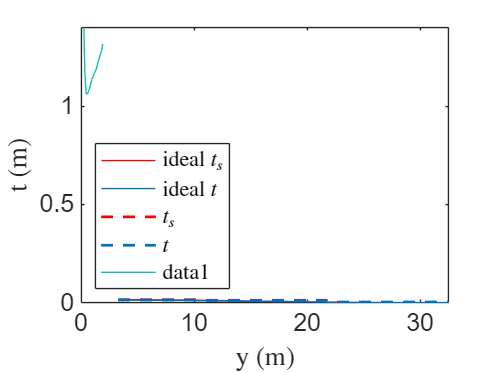

As_bt_vals =     0.2181    0.2380    0.2597    0.2808    0.3025    0.3173    0.3448    0.3971    0.4224    0.5274    0.6325    0.6879    0.7375    0.8426    0.9299    0.9476    1.0527    1.1577    1.2628    1.3244    1.3678    1.4728    1.5729    1.5779    1.6829    1.7880    1.8225    1.8930


ts_t_vals =     1.4000    1.3474    1.2947    1.2421    1.1895    1.1621    1.1368    1.0842    1.0612    1.0627    1.0730    1.0842    1.0933    1.1183    1.1368    1.1399    1.1505    1.1687    1.1818    1.1895    1.1984    1.2245    1.2421    1.2434    1.2640    1.2819    1.2947    1.3174


% Precompute parameters
c = wb.c_c .* wing_opt.cn; 
b2 = wb.b2_c .* wing_opt.cn;
N = M ./ c ./ b2;
E = Al7068.E;
sigmaY = Al7068.sigma_y;
sigmaYT = Al7068.sigma_y_tensile;
rho_Uskin = Al7068.rho;
Nneg = Mneg ./ c ./ b2;
d_hratio = 0.3;
    
%Find ideal t
%find corresponding factors scr/s0 and F
[As_bt_vals, ts_t_vals] = findAsbt_ts_for_fb_f0(min(sigmaY./sigma_max,1.4), 20, 20)

bestF = 0;
bestM = Inf;
Flist = interpF(As_bt_vals, ts_t_vals);
Flist = Flist(~isnan(Flist));
for i = 1:length(Flist)
    F = Flist(i);
    As_bt = As_bt_vals(i);
    ts_t = ts_t_vals(i);

    %t = max(0e-3,-Nneg./sigma_max);
    t = max(0e-3,N./sigmaY);
    ts = max(0e-3,t.*ts_t);
    
    %convert to 3 increments
    wb.t_Upper = thicknessDoubler(t,wing_opt.stripy,D);
    wb.ts_Upper = thicknessDoubler(ts,wing_opt.stripy,D);
    
    %Find stringer number
    %interpolate Ks
    Ks = 3.62.*ones(size(t));
    bs2 = 0.1.*ones(size(t));
    wb.sr_s0 = sigmaY./sigma_max;
    converged = false;
    while converged == false
        bs = max(0, wb.t_Upper.*(sigmaY./(wb.sr_s0.*Ks.*E)).^(-1/2)); %Stringer pitch
        %bs = wb.t_Upper.*sqrt((wb.t_Upper.*Ks.*E)./max(N,0));
        %convert ideal N to discrete N
        %idealN = wing_opt.cn./bs;
        %[pks, locs] = findpeaks(idealN(wingidx), wing_opt.stripy(wingidx), 'NPeaks', 3, 'SortStr', 'descend');
        %wb.N = StringerNumber5Increments(idealN,wing_opt.stripy,D);
        wb.b1_c = bs./wing_opt.cn;
        
        %find hs from As/bt
        wb.hs = As_bt./(ts_t.*1.6./(bs));
        %wb.hs = StringerHeight5Increments(wb.hs,wing_opt.stripy,D);
        Ks = interpKsSkinStringer(wb.hs./bs, ts_t);
        wb.ds = wb.hs*d_hratio;
        wb = wb.calcStringerArea();
        
        %interpolate actual sr_s0 and F
        wb = wb.interpsr_s0(scr_s0,wing_opt);
        wb = wb.interpretF(F_data, wing_opt);
        
        err = sqrt(nanmean((bs - bs2).^2))
        if err < 2e-4
            converged = true;
        end
        bs2 = bs;
    end
    
    wb.Ks_Upper = Ks;
    %Find ideal L from local buckling formula
    idealL = N.*E.*(sigmaY./wb.F).^(-2); %buckling load = yield stress
    wb.L = max(idealL, 0.5); %constrain to minimum 1m separation
    [wb.yrib, wb.Nrib] = createRibLocationsFromL(wb.L, wing_opt, D);
    wb = wb.mapRibSpacing(wing_opt,D);

    


    %Find stress
    wbStress = wingboxStress();
    wbStress.wb = wb;
    wbStress = wbStress.findGlobalStress(M,wing_opt,Al2024, wb.t_Upper);
    wbStress = wbStress.findLocalStress(M,wing_opt,Al2024);
    



    %For verify interactive buckling in later parts
    sigmacr_Uskin = wbStress.s_cr_local_skin;
    sigma_Uskin = N./wb.t_Upper;


    %mass  
    dy = wing_opt.stripy(2) - wing_opt.stripy(1);
    V_Uskin = 2*trapz(wing_opt.stripy(wingidx), wb.t_Upper(1)*wb.c_c.*wing_opt.cn(wingidx)); %plate
    As_Upper = mean(wb.ts_Upper).*wb.hs.*(1 + 2*0.3);
    V_Uskin_skin = V_Uskin
    V_Uskin_stringer = 2*trapz(wing_opt.stripy(wingidx), As_Upper(wingidx)./wb.b1_c(wingidx))
    V_Uskin_total = V_Uskin + V_Uskin_stringer;
    M_skin = rho_Uskin*V_Uskin_total
    if M_skin < bestM && ~isnan(F)
        bestF = F;
        bestM = M_skin
    end
end

err = 0.1814

err = 0.2583

err = 0

V_Uskin_skin = 0.7551

V_Uskin_stringer = NaN

Error using  * 
Too many output arguments.



figure(1)
clf;
%for plotting
As_opt = wb.ts_Upper .* wb.hs .* (1 + 2*d_hratio);
xq_opt = As_opt ./ (wb.b1_c .* wing_opt.cn) ./ wb.t_Upper;
plot(wing_opt.stripy, xq_opt)
hold on
yline(As_bt)
ylabel("A/bt")
xlabel("y (m)")
xlim([0 wing_opt.b/2])

figure(2)
clf;
plot(wing_opt.stripy(wingidx),ts(wingidx),'r')
hold on
plot(wing_opt.stripy(wingidx),t(wingidx),'Color', [0 0.4470 0.7410])
hold on
plot(wing_opt.stripy(wingidx), wb.ts_Upper(wingidx),'r--','LineWidth',1.5)
hold on
plot(wing_opt.stripy(wingidx), wb.t_Upper(wingidx), 'Color', [0 0.4470 0.7410], 'LineStyle', '--', 'LineWidth', 1.5)
xlim([0, wing_opt.b/2])
ylabel("t (m)","Interpreter","latex")
xlabel("y (m)","Interpreter","latex")
legend("ideal $t_s$", "ideal $t$","$t_s$","$t$","Interpreter","latex","Location","southwest")
print(gcf, fullfile('images', 'Uplate_t.png'), '-dpng', '-r300');

figure(3)
clf;
plot(wing_opt.stripy(wingidx), wb.b1_c(wingidx).*wing_opt.cn(wingidx),'LineWidth',1.5)
hold on
plot(wing_opt.stripy(wingidx), wb.hs(wingidx),'LineWidth',1.5)


xlim([0, wing_opt.b/2])
ylabel("metres","Interpreter","latex")
xlabel("y (m)","Interpreter","latex")
legend("Stringer pitch","Stringer height","Interpreter","latex","location","southwest")
print(gcf, fullfile('images', 'Uplate_N.png'), '-dpng', '-r300');

figure(4)
clf;
plot(wing_opt.stripy(wingidx), max(idealL(wingidx),0),'Color', [0 0.4470 0.7410])
hold on
plot(wing_opt.stripy(wingidx), wb.L(wingidx),'LineWidth',1.5)

xlim([0, wing_opt.b/2])
ylabel("L (m)","Interpreter","latex")
xlabel("y (m)","Interpreter","latex")
legend("computed spacing","actual rib spacing","Interpreter","latex","Location","southwest")
print(gcf, fullfile('images', 'RibSpacing.png'), '-dpng', '-r300');

Finally display stress

figure(5)
clf;
% Global Buckling: Solid Blue, Thick
sigmaLocal =  wb.sr_s0.*wb.Ks_Upper.*E.*(wb.t_Upper./(wb.b1_c.*wing_opt.cn)).^2;
plot(wing_opt.stripy(wingidx), sigmaLocal(wingidx)*1e-6, ...
    'LineStyle', '--', 'Color', [0, 0.4470, 0.7410], 'LineWidth', 2);
hold on;
% Local Buckling: Dashed Orange, Medium
plot(wing_opt.stripy(wingidx), wbStress.s_cr_local_skin(wingidx).*1e-6, ...
    'LineStyle', '-', 'Color', [0.8500, 0.3250, 0.0980], 'LineWidth', 1.5);
% Compressive Load: Dotted Green, Thick
plot(wing_opt.stripy(wingidx), N(wingidx)./wb.t_Upper(wingidx)*1e-6, ...
    'LineStyle', ':', 'Color', [0.4660, 0.6740, 0.1880], 'LineWidth', 2);
% Tensile Load: Dash-Dot Purple, Medium
plot(wing_opt.stripy(wingidx), -Nneg(wingidx)./wb.t_Upper(wingidx)*1e-6, ...
    'LineStyle', '-.', 'Color', [0.4940, 0.1840, 0.5560], 'LineWidth', 1.5);
% Compressive Yield: Solid Black
yline(sigmaY*1e-6, 'LineStyle', '-', 'Color', 'k', 'LineWidth', 1);
% Tensile Yield: Dashed Black
yline(sigmaYT*1e-6, 'LineStyle', '--', 'Color', 'k', 'LineWidth', 1);

legend("Global Buckling","Local Buckling","Compressive Load","Tensile Load",...
    "Compressive Yield Stress","Tensile Yield Stress", "Interpreter","latex","Location","northwest");
xlabel("y (m)", "Interpreter", "latex");
ylabel("$\sigma$ (MPa)", "Interpreter", "latex");
xlim([0 wing_opt.s]);
ylim([0 1000])
print(gcf, fullfile('images', 'UplateStressDiagram.png'), '-dpng', '-r300');

Display rib

figure(6)
clf;
wing_opt.plotWing
hold on
wb.plotRibs(wing_opt)
hold on
wb.plotWingBox(wing_opt,D)
ylim([0 wing_opt.b/2*1.02])
axis equal
print(gcf, fullfile('images', 'WingandRib.png'), '-dpng', '-r300');

# **Lower Skin**

% Precompute parameters
c = wb.c_c .* wing_opt.cn;
b2 = wb.b2_c .* wing_opt.cn;
N = M ./ c ./ b2;
Nneg = -Mneg ./ c ./ b2; %compressive load due to negative loading
E = Al7068.E;


sigmaYT = Al7068.sigma_y_tensile;
sigmaY = Al7068.sigma_y;

[As_bt_vals, ts_t_vals] = findAsbt_ts_for_fb_f0(sigmaY/sigma_max, 500, 500);

for i = 1:length(As_bt_vals)
    F = interpF(As_bt_vals(i), ts_t_vals(i));
    if F > bestF
        bestF = F;
        As_bt = As_bt_vals(i);
        ts_t = ts_t_vals(i);
    end
end
F = bestF;

t = max(0e-3, N./sigma_max);
ts = max(0e-3,t.*ts_t);

wb.t_Lower = thicknessDoubler(t,wing_opt.stripy,D);
wb.ts_Lower = thicknessDoubler(ts,wing_opt.stripy,D);

%Find stringer number
%interpolate Ks
Ks = 3.62.*ones(size(t));
bs2 = 0.2.*ones(size(t));
wb.sr_s0_Lower = sigmaY./sigma_max;
converged = false;

while converged == false
    bs = max(0, wb.t_Lower.*(sigmaY./(wb.sr_s0_Lower.*Ks.*E)).^(-1/2)); %Stringer pitch

    %idealN = wing_opt.cn./bs;
    %[pks, locs] = findpeaks(idealN(wingidx), wing_opt.stripy(wingidx), 'NPeaks', 3, 'SortStr', 'descend');
    %wb.N_Lower = StringerNumber5Increments(idealN,wing_opt.stripy,D);
    wb.b1_c_Lower = bs./wing_opt.cn;
    
    %find hs from As/bt
    wb.hs_Lower = As_bt./(ts_t.*1.6./bs);
    Ks = interpKsSkinStringer(wb.hs_Lower./bs, ts_t);
    wb.ds_Lower = wb.hs_Lower*d_hratio;
    wb = wb.calcStringerArea_Lower();
    
    %interpolate actual sr_s0 and F
    wb = wb.interpsr_s0_Lower(scr_s0,wing_opt);
    wb = wb.interpretF_Lower(F_data, wing_opt);
    
    err = sqrt(nanmean((bs - bs2).^2))
    if err < 2e-3
        converged = true;
    end
    bs2 = bs;
end

wb.Ks_Lower = Ks;

%Stress diagram
figure(7)
clf;
% Global Buckling: Solid Blue, Thick
sigmaGlobal =  wb.sr_s0_Lower.*wb.Ks_Lower.*E.*(wb.t_Lower./(wb.b1_c_Lower.*wing_opt.cn)).^2;
plot(wing_opt.stripy(wingidx), sigmaGlobal(wingidx)*1e-6, ...
    'LineStyle', '-', 'Color', [0, 0.4470, 0.7410], 'LineWidth', 2);
hold on;
sigmaLocal = wb.F_Lower.*sqrt(Nneg.*E./wb.L)
% Local Buckling: Dashed Orange, Medium
plot(wing_opt.stripy(wingidx), sigmaLocal(wingidx).*1e-6, ...
    'LineStyle', '--', 'Color', [0.8500, 0.3250, 0.0980], 'LineWidth', 1.5);
% Compressive Load: Dotted Green, Thick
plot(wing_opt.stripy(wingidx), Nneg(wingidx)./wb.t_Lower(wingidx)*1e-6, ...
    'LineStyle', ':', 'Color', [0.4660, 0.6740, 0.1880], 'LineWidth', 2);
% Tensile Load: Dash-Dot Purple, Medium
plot(wing_opt.stripy(wingidx), N(wingidx)./wb.t_Lower(wingidx)*1e-6, ...
    'LineStyle', '-.', 'Color', [0.4940, 0.1840, 0.5560], 'LineWidth', 1.5);
% Compressive Yield: Solid Black
yline(sigmaY*1e-6, 'LineStyle', '-', 'Color', 'k', 'LineWidth', 1);
% Tensile Yield: Dashed Black
yline(sigmaYT*1e-6, 'LineStyle', '--', 'Color', 'k', 'LineWidth', 1);

legend("Global Buckling","Local Buckling","Compressive Load","Tensile Load",...
    "Compressive Yield Stress","Tensile Yield Stress", "Interpreter","latex","Location","northwest");
xlabel("y (m)", "Interpreter", "latex");
ylabel("$\sigma$ (MPa)", "Interpreter", "latex");
xlim([0 wing_opt.s]);
ylim([0 1000])
print(gcf, fullfile('images', 'LplateStressDiagram.png'), '-dpng', '-r300')

## **2. Rib**

%Calculate effective panel thickness of upper and lower
t_eff_upper = wb.t_Upper + wb.As./wb.b1_c./wing_opt.cn;
t_eff_lower = wb.t_Lower + wb.As_Lower./wb.b1_c_Lower./wing_opt.cn;

E = Al2024.E;
chord = wing_opt.cn;
h = wb.b2_c.*wing_opt.cn;
s = wb.a;
sigma_y = Al2024.sigma_y;

%Find moment of inertia
I_Upper = chord .* (t_eff_upper).^3 ./ 12 + chord .* (t_eff_upper) .* (h./2).^2;
I_Lower = chord .* (t_eff_lower).^3 ./ 12 + chord .* (t_eff_lower) .* (h./2).^2;

%Crush load
F = @(M,s,h,t_e,chord,E,I) (M.^2 .* s .* h .* ...
    (t_e) .* chord ./ 2) ./ ...
    (E .* I.^2);
%There are 4 combinations of crush load: pos upper, pos lower, neg upper
%and neg lower
F_pos_upper = F(M, wb.L, h, t_eff_upper, wing_opt.cn, E, I_Upper)
F_neg_upper = F(Mneg, wb.L, h, t_eff_upper, wing_opt.cn, E, I_Upper)
F_pos_lower = F(M, wb.L,h, t_eff_lower, wing_opt.cn, E, I_Lower)
F_neg_lower = F(Mneg, wb.L, h, t_eff_lower, wing_opt.cn, E, I_Lower)
figure(1)
clf;
plot(wing_opt.stripy,F_pos_upper)
hold on
plot(wing_opt.stripy,F_pos_lower)
hold on
plot(wing_opt.stripy,F_neg_upper)
hold on
plot(wing_opt.stripy,F_neg_lower)
legend("upper+","lower+","upper-","lower-", "Interpreter", "latex")
xlim([0, wing_opt.b/2])
ylim([0, 700000])
xlabel("y (m)", "Interpreter", "latex")
ylabel("Crush Load (N)", "Interpreter", "latex")
print(gcf, fullfile('images', 'CrushDiagram.png'), '-dpng', '-r300');


%design rib thickness
%tr = F/sigmaYc
tr1 = F_pos_lower ./ sigma_y ./ wing_opt.cn;
tr2 = sqrt(sigma_y/3.62/E).*wb.b2_c.*wing_opt.cn;
tr3 = (F_pos_lower.*h.^2./(3.62.*E.*wing_opt.cn)).^(1/3);
figure(2)
clf;
plot(wing_opt.stripy(wingidx),tr3(wingidx)*1000)
hold on
scatter(wb.yrib,interp1(wing_opt.stripy,tr3*1000,wb.yrib))

legend("Ideal thickness","Thickness at each rib")
xlim([0, wing_opt.b/2])
xlabel("y (m)", "Interpreter", "latex")
ylabel("t (mm)", "Interpreter", "latex")
print(gcf, fullfile('images', 'tr.png'), '-dpng', '-r300');

wb.tr = interp1(wing_opt.stripy,tr3,wb.yrib)

## **3. Spar buckling analysis(get spar thickness)**

**Web is fixed at top/bottom, SS at sides (web stringers)**

%[t_FS, t_RS] = Sparfun(wb, wing_opt,material,V,T,wbStress)

%for maximum buckling coefficient, let a = h
wb.a = wb.b2_c.*wing_opt.cn;
Ks = 8.1;
E = Al7068.E;

%Use same As/bt and ts/t
%z stringer
figure(1)
clf;
plot(wing_opt.stripy(wingidx), S(wingidx))
hold on
plot(wing_opt.stripy(wingidx), Sneg(wingidx))
xlim([0 wing_opt.b/2])

Awb = wb.c_c.*wb.b2_c.*wing_opt.cn.*wing_opt.cn;
hwb = wb.b2_c.*wing_opt.cn;

q = @(S,T,h,A) S./(2*h) + T./(2*A);

qFpos = q(-S,tau,hwb,Awb);
qFneg = q(-Sneg,tau,hwb,Awb);
qRpos = q(-S,-tau,hwb,Awb);
qRneg = q(-Sneg,-tau,hwb,Awb);

figure(2);
clf;

% Define line styles/colors for clarity
front_color = [0, 0.4470, 0.7410];  % Blue for front
rear_color = [0.8500, 0.3250, 0.0980];  % Red for rear
linewidth = 2;  % Thicker lines for visibility

% Plot front (+/-)
plot(wing_opt.stripy(wingidx), abs(qFpos(wingidx)), ...
    'Color', front_color, 'LineStyle', '-', 'LineWidth', linewidth);
hold on;
plot(wing_opt.stripy(wingidx), abs(qFneg(wingidx)), ...
    'Color', front_color, 'LineStyle', '--', 'LineWidth', linewidth);

% Plot rear (+/-)
plot(wing_opt.stripy(wingidx), abs(qRpos(wingidx)), ...
    'Color', rear_color, 'LineStyle', '-', 'LineWidth', linewidth);
plot(wing_opt.stripy(wingidx), abs(qRneg(wingidx)), ...
    'Color', rear_color, 'LineStyle', '--', 'LineWidth', linewidth);

% Formatting
legend("Front, +", "Front, -", "Rear, +", "Rear, -", ...
    'Interpreter', 'latex', 'Location', 'best');
ylabel("$\left| q \right|$ (N/m)", "Interpreter", "latex");
xlabel("$y$ (m)", "Interpreter", "latex");
xlim([0, wing_opt.b/2]);

[y_spar_s, N_spar_s] = createRibLocationsFromL(wb.b2_c.*wing_opt.cn, wing_opt, D);
y_wing = wing_opt.stripy;
yrib   = y_spar_s;

% Sort yrib if not already sorted
yrib = sort(yrib);

% Pre-allocate L
L = zeros(size(y_wing));

for i = 1:length(y_wing)
    y_i = y_wing(i);

    % 1) Check if y_i is within [-D/2, D/2]
    if (y_i >= -D/2) && (y_i <= D/2)
        % If in the fuselage region, set L to NaN
        L(i) = NaN;
    else
        % 2) Otherwise, find the adjacent ribs
        k = find(yrib <= y_i, 1, 'last');

        if isempty(k)
            % y_i < yrib(1)
            L(i) = yrib(2) - yrib(1);
        elseif k == length(yrib)
            % y_i >= yrib(end)
            L(i) = yrib(end) - yrib(end-1);
        else
            % y_i lies between yrib(k) and yrib(k+1)
            L(i) = yrib(k+1) - yrib(k);
        end
    end
end

a = L;
wb.a = L;

% Initialize an array to store the indices
sparidx = NaN(size(y_spar_s)); % Use NaN for excluded points

% Loop through each point in y_spar_s
for i = 1:length(y_spar_s)
    % Find the index of the closest point in wing_opt.stripy
    [~, idx] = min(abs(wing_opt.stripy - y_spar_s(i)));
    
    % Check if the corresponding wing_opt.stripy value is within the desired range
    if abs(wing_opt.stripy(idx)) >= D/2
        sparidx(i) = idx; % Store the index if the condition is satisfied
    end
    % Otherwise, sparidx(i) remains NaN (excluded)
end



figure(3)
clf;
plot(wing_opt.stripy(wingidx), wb.b2_c.*wing_opt.cn(wingidx),'LineWidth',1.6)
hold on
scatter(wing_opt.stripy(sparidx), wb.a(sparidx),'x','r')
hold on
plot(wing_opt.stripy(wingidx), wb.a(wingidx),'r')
legend("Ideal $a$ = $h_{wb}$","Stiffener location","Actual $a$", "Interpreter", "latex")
xlabel("y (m)", "Interpreter", "latex")
ylabel("Spar stiffener spacing (m)", "Interpreter", "latex")
xlim([0 wing_opt.b/2])
print(gcf, fullfile('images', 'aspar.png'), '-dpng', '-r300');
wb.y_sparS = wing_opt.stripy(sparidx);

q_FS = abs(qFneg);
q_RS = abs(qRpos);

t_FS = (q_FS .* b2 ./ Ks ./ E).^(1/3);%thickness front spar
t_RS = (q_RS .* b2 ./ Ks ./ E).^(1/3);%thickness

tFd = [0.019 0.016 0.011]
tRd = [0.02 0.018 0.013]

wb.tF = d2c(wing_opt,tFd);
wb.tR = d2c(wing_opt,tRd);



figure(4)
clf;
plot(wing_opt.stripy(wingidx),t_FS(wingidx),'r')
hold on
plot(wing_opt.stripy(wingidx),t_RS(wingidx),'Color', [0 0.4470 0.7410])
hold on
plot(wing_opt.stripy(wingidx),wb.tF(wingidx),'r--','LineWidth',1.5)
hold on
plot(wing_opt.stripy(wingidx),wb.tR(wingidx), 'Color', [0 0.4470 0.7410], 'LineStyle', '--', 'LineWidth', 1.5)
legend("Front spar ideal","Rear spar ideal", "Front spar","Rear spar","Location","SouthWest","Interpreter", "latex")
xlim([0, wing_opt.b/2]);
xlabel("y(m)", "Interpreter", "latex")
ylabel("thickness (m)", "Interpreter", "latex")
ylim([0 0.021])
print(gcf, fullfile('images', 'tspar.png'), '-dpng', '-r300');


t_sFS = 1.076 * wb.tF;
t_sRS = 1.076 * wb.tR;

%A = ts hs * 1.6
%hs = A / (1.6ts)

%A/at = 1.672
%A = 1.672 a t

%hs = (1.672 a t)/(1.6 ts)
h_sFS = (1.672.*wb.a.*wb.tF)./(1.6.*t_sFS)
h_sRS = (1.672.*wb.a.*wb.tR)./(1.6.*t_sRS)
figure(5)
clf;
scatter(wing_opt.stripy(sparidx), h_sFS(sparidx))
ylabel("spar stiffener height (m)")
xlim([0 wing_opt.b/2])
print(gcf, fullfile('images', 'hss.png'), '-dpng', '-r300');

% %Verify interactive buckling in spar
% %check front spar
% tau_cr = 8.1*E.*(wb.tF./wb.a).^2;
% tau_cr_tresca = 125*1e6;
% tau_0 = qFneg./wb.tF;
% 
% Asbt_spar = t_sFS.*h_sFS*1.6./(wb.a.*t_sFS);
% ts_t_spar = 1.076;
% 
% R_c = interpsr_s0(Asbt_spar,ts_t_spar);
% R_s = tau_cr_tresca/tau_0;

IxFS = 1/12*wb.tF.*(wb.b2_c.*wing_opt.cn).^3;
sigma_cFS = M.*wb.b2_c.*wing_opt.cn/2./IxFS

IxRS = 1/12*wb.tR.*(wb.b2_c.*wing_opt.cn).^3;
sigma_cRS = M.*wb.b2_c.*wing_opt.cn/2./IxRS

## 4. Dcell

sigmaY = Al7068.sigma_y_tensile;
sigma_yield_tens = Al7068.sigma_y_tensile; % [Pa] From your material data
E = Al7068.E;                              % [Pa] Young’s modulus
b_D = pi * wb.R_c .* wing_opt.cn;          % [m] D-cell circumference (already computed)
[yprib, Nprib] = createRibLocationsFromL(b_D, wing_opt, D);

y_wing = wing_opt.stripy;
yrib   = yprib;

% Sort yrib if not already sorted
yrib = sort(yrib);

% Pre-allocate L
L = zeros(size(y_wing));

for i = 1:length(y_wing)
    y_i = y_wing(i);

    % 1) Check if y_i is within [-D/2, D/2]
    if (y_i >= -D/2) && (y_i <= D/2)
        % If in the fuselage region, set L to NaN
        L(i) = NaN;
    else
        % 2) Otherwise, find the adjacent ribs
        k = find(yrib <= y_i, 1, 'last');

        if isempty(k)
            % y_i < yrib(1)
            L(i) = yrib(2) - yrib(1);
        elseif k == length(yrib)
            % y_i >= yrib(end)
            L(i) = yrib(end) - yrib(end-1);
        else
            % y_i lies between yrib(k) and yrib(k+1)
            L(i) = yrib(k+1) - yrib(k);
        end
    end
end

wb.a_D = L;

figure(1)
clf;
plot(wing_opt.stripy(wingidx),b_D(wingidx),'LineWidth',1.5)
hold on
plot(wing_opt.stripy(wingidx),wb.a_D(wingidx))
legend("Ideal = $b_D$","Actual = $a_D$","Location","SouthWest","Interpreter", "latex")
xlim([0, wing_opt.b/2]);
xlabel("y(m)", "Interpreter", "latex")
ylabel("Pseudorib spacing (m)", "Interpreter", "latex")
print(gcf, fullfile('images', 'pseudorib.png'), '-dpng', '-r300');

wb.Nprib =58; 

a_D = wb.a_D;
b_D = pi*wb.R_c.*wing_opt.cn;
R = wb.R_c.*wing_opt.cn;
taumax = sigmaY/2;

%initial guess
t1 = 20e-3*ones(size(wing_opt.stripy));
t2 = 20e-3*ones(size(wing_opt.stripy));
converged = false
iter = 0 
maxiter = 6
figure
while converged == false && iter < maxiter
    q_D = [];
    t1 = real(t2);
    for j =1:length(wingidx)
        i = wingidx(j);
        [~, q_D(i)] = shearFlow(wing_opt.cn(i), wb, tau(i), wb.t_Upper(i), wb.t_Lower(i), wb.tF(i), wb.tR(i), t1(i));
        %shear stress = q / t = buckling shear stress
    end
    b_RT = b_D./sqrt(R.*t1);
    b_RT = b_RT(wingidx);
    Ks = [];
    for j =1:length(wingidx)
        i = wingidx(j);
        Ks(i) = interpKspolyfit(R(i),t1(i),a_D(i),b_D(i));
    end
    %t2 = q_D./(Ks.*E.*t1.^2./b_D.^2);
    t2 = b_D.*sqrt((q_D./t1)./(Ks.*E));
    if abs(max(t2) - max(t1)) < 1e-4
        converged = true;
        disp("Converged")
    end
    plot(wing_opt.stripy(wingidx),t2(wingidx)*1000)
    hold on
    iter = iter + 1;
    disp(max(t2))
    %converged = true
end

hold on
yline(max(t2)*1000,'--')
xlabel("y (m)","Interpreter","latex")
ylabel("$t_D$ (mm)","Interpreter","latex")
legend("i=1","i=2","i=3","Converged value","Interpreter","Latex","Location","SouthWest")
wb.tD = max(t2);
wb.tr_D = 3e-3;
ylim([0 7.3])
%print(gcf, fullfile('images', 'tD.png'), '-dpng', '-r300');

Interactive Buckling

Verify for upper and lower skin, front and rear spar

qF = -S./(2.*wb.b2_c.*wing_opt.cn);
qFneg = -Sneg./(2.*wb.b2_c.*wing_opt.cn);



q_wb = [];
q_D = [];
q_wbneg = [];
q_Dneg = [];
for j = 1:length(wingidx)
    i = wingidx(j);
    [q_wb(i), q_D(i)] = shearFlow(wing_opt.cn(i), wb, tau(i), wb.t_Upper(i), wb.t_Lower(i), wb.tF(i), wb.tR(i), wb.tD);
    [q_wbneg(i), q_Dneg(i)] = shearFlow(wing_opt.cn(i), wb, tauneg(i), wb.t_Upper(i), wb.t_Lower(i), wb.tF(i), wb.tR(i), wb.tD);
end



figure(1)
clf;
plot(wing_opt.stripy(wingidx),q_wb(wingidx))
hold on
plot(wing_opt.stripy(wingidx),abs(q_wbneg(wingidx)),'--')
hold on
plot(wing_opt.stripy(wingidx),abs(q_D(wingidx)))
hold on
plot(wing_opt.stripy(wingidx),abs(q_Dneg(wingidx)),'--')
legend("Upper/lower skin, +","Upper/lower skin, -","D-cell, +","D-cell, -")
ylabel("shear flow magnitude (N/m)")
xlim([0 wing_opt.b/2])

sigmacrs = Al7068.sigma_y_tensile./2;

%in upper skin, q_wb
RcU = sigma_Uskin./sigmacr_Uskin
RsU = q_wb./wb.t_Upper./sigmacrs

%in lower skin, q_wb
RcL = sigma_Lskin./sigmacr_Lskin
RsL = q_wb./wb.t_Lower./sigmacrs

xspace = linspace(0,1,100);
figure(2)
clf;
scatter(RcU(wingidx),RsU(wingidx),'x')
hold on
scatter(RcL(wingidx),RsL(wingidx),'.')
hold on
plot(xspace, sqrt(0.99-xspace),'k','LineWidth',1.5)
xlabel("$R_c$","Interpreter","latex")
ylabel("$R_s$","Interpreter","latex")
legend("Upper skin","Lower skin","Envelope")
print(gcf, fullfile('images', 'Interactive Buckling.png'), '-dpng', '-r300');

%find index that RcU + RsU^2 > 0.99
idx = find(RcU + RsU.^2 > 0.99);
wing_opt.stripy(idx)

Mass Analysis

dy = wing_opt.stripy(2) - wing_opt.stripy(1);
%1. upper skin = skin + stringers
rho_Uskin = Al7068.rho;
V_Uskin = 2*trapz(wing_opt.stripy(wingidx), wb.t_Upper(1)*wb.c_c.*wing_opt.cn(wingidx)); %plate
As_Upper = mean(wb.ts_Upper).*wb.hs.*(1 + 2*0.3);
V_Uskin_skin = V_Uskin
V_Uskin_stringer = 2*trapz(wing_opt.stripy(wingidx), As_Upper./wb.b1_c)
V_Uskin_total = V_Uskin + V_Uskin_stringer
M_skin = rho*Uskin*V_Uskin_total;

%2. lower skin
rho_Lskin = Al7068.rho;
V_Lskin = 2*trapz(wing_opt.stripy(wingidx), wb.t_Lower(1)*wb.c_c.*wing_opt.cn(wingidx) ); %plate
As_Lower = mean(wb.ts_Lower).*wb.hs_Lower.*(1 + 2*0.3);
N1 = wb.N_Lower(169);
N2 = wb.N_Lower(205);
N3 = wb.N_Lower(289);
[L1, L2, L3] = getStringerLengths(wb.N_Lower, wing_opt.stripy, D);
V_Lskin_skin = V_Lskin
V_Lskin_stringer = 2*(L1*N1*As_Lower + L2*N2*As_Lower + L3*N3*As_Lower)
V_Lskin = V_Lskin + V_Lskin_stringer

%3. ribs
crib = [];
for i = 1:length(wb.yrib)
    crib(i) = wing_opt.c_at_y(wb.yrib(i));
end
Ar = (wb.c_c .* wb.b2_c .*crib.^2)
V_ribs = sum(wb.tr.* Ar')

%4. front spar
ywing = wing_opt.stripy(wingidx);
tFwing = wb.tF(wingidx);
hF = [];
for i = 1:length(ywing)
    hF(i) = wb.b2_c.*wing_opt.c_at_y(ywing(i));
end
V_FS = trapz(ywing, hF.*tFwing)*2;
As_FS = h_sFS(wingidx).*t_sFS(wingidx).*(1 + 0.3*2);

V_FS_skin = V_FS
V_FS_stiffeners =  trapz(ywing,As_FS)*2
V_FS = V_FS  +V_FS_stiffeners


%5. rear spar
tRwing = wb.tR(wingidx);
V_RS = trapz(ywing, hF.*tRwing);
As_RS = h_sRS(wingidx).*t_sRS(wingidx).*(1 + 0.3*2);
V_RS_skin = V_RS
V_RS_stiffeners =  trapz(ywing,As_RS)*2
V_RS = V_RS  +V_RS_stiffeners

%6. D cell
V_D = trapz(ywing, wb.tD.*pi.*wb.R_c.*wing_opt.cn(wingidx))*2;
V_D = V_D + sum(wb.tr_D.*1/2.*pi*(wb.R_c.*wing_opt.cn(wingidx)).^2)*2
